**LEP 4-4: Rate law for SO2 Oxidation**

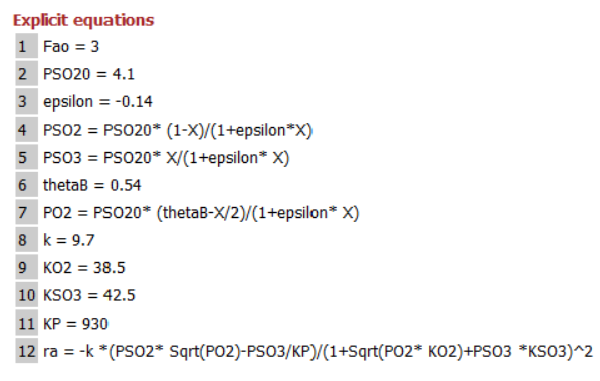

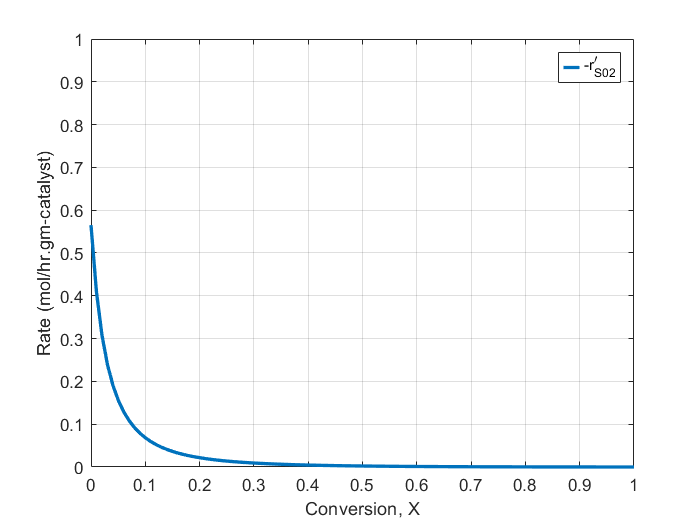

PSO20=4.1;
thetaB=0.54;
k=9.7;
KO2=38.5;
KSO3=42.5;
KP=930;
X=linspace(0,1,100);
epsilon=-0.14;
for i=1:100
PSO2(i) = PSO20*(1 - X(i))./(1 + epsilon*X(i));
PSO3(i) = PSO20*X(i)./(1 + epsilon*X(i));
PO2(i) = PSO20* (thetaB - X(i)/2)./(1 + epsilon*X(i));
Rate(i)=k*(PSO2(i).* sqrt(PO2(i)) - PSO3(i)/KP)./(1 + sqrt(PO2(i)*KO2) + PSO3(i)*KSO3).^2;
end
plot(X,Rate,'LineWidth',2)
axis([0 1 0 1])
xlabel('Conversion, X')
ylabel('Rate (mol/hr.gm-catalyst)')
grid on
leg=legend('-r^\prime_{S02}');
leg.ItemTokenSize=[10,10];